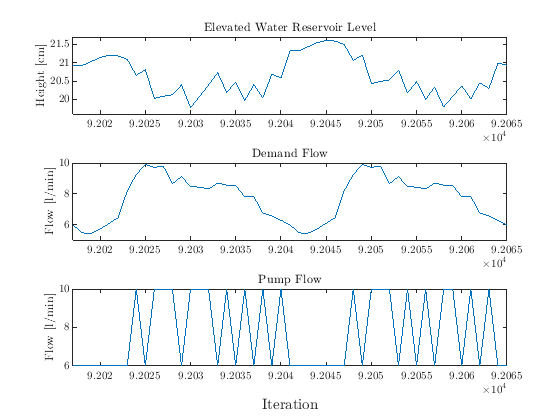

clear all; close all; clc
load("DoubleContWorkspace.mat")


actualhi = Tanklevel;

flow = [6 8 10];

for i=1:maxstep
    pflow(i) = flow(pump(i));
end



fig = figure(9);
    ha(1)=subplot(3,1,1);
    plot(actualhi)
    ylabel('Height [cm]')
    ylim([19.6 21.7]);
    title('Elevated Water Reservoir Level')
    ha(2)=subplot(3,1,2);
    plot(demandvector)
    ylabel('Flow [l/min]')
    title('Demand Flow')
    ha(3)=subplot(3,1,3);
    plot(pflow)
    ylabel('Flow [l/min]')
    title('Pump Flow')
    linkaxes(ha,'x')
    xlim([0.92*maxstep+17 0.92*maxstep+48+17])
    han=axes(fig,'visible','off'); 
    han.XLabel.Visible='on';
    xlabel(han,'Iteration');

    
     fig = figure(19);
    hb(1)=subplot(2,1,1);
    plot(actualhi)
    ylabel('Height [cm]')
    ylim([10 50]);
    title('Elevated Water Reservoir Level')
    hb(2)=subplot(2,1,2);
    plot(EPaveragecost(1,:))
    ylabel('MA cost')
    title('Moving average cost')
    xlim([0 10000]);
    linkaxes(hb,'x')

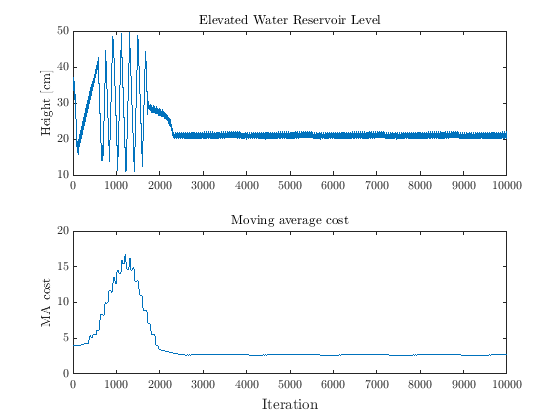

    han=axes(fig,'visible','off'); 
    han.XLabel.Visible='on';
    xlabel(han,'Iteration');


    
%     
%      figure(21)
% for i = 1:ep
% figure()
% plot(Q1(i,:)')
% hold on
% plot(Q2(i,:)')
% plot(Q3(i,:)')
% legend('$\hat{Q}\big(24,\textbf{w}_{1,1}\big)$', '$$\hat{Q}\big(24,\textbf{w}_{1,2}\big)$', '$$\hat{Q}\big(24,\textbf{w}_{1,3}\big)$','location','best')
% end
%      title('Q convergence')
%      xlabel('Iteration') 
%     ylabel('Q value')
%   
    
%     
%     figure(20)
%     plot(actualhi)
%     xlim([0 0.1*maxstep])
%     title('Elevated Water Reservoir Level')
%     xlabel('Iteration') 
%     ylabel('Height')
% 
%     
%      figure(21)
%     plot(actualhi)
%     xlim([0.85*maxstep maxstep])
%     title('Elevated Water Reservoir Level')
%     xlabel('Iteration') 
%     ylabel('Height')

    
%exportgraphics(figure(9), fullfile('..\..\Report\figures','ContiniousHResults1.pdf'))
%exportgraphics(figure(19), fullfile('..\..\Report\figures','ContiniousHResults2.pdf'))
%exportgraphics(figure(20), fullfile('..\..\Report\figures','ContiniousHResults3.pdf'))
%exportgraphics(figure(21), fullfile('..\..\Report\figures','ContiniousHResults4.pdf'))

%exportgraphics(figure(19), fullfile('..\..\Report\figures','RemovedCenter.pdf'))

